% TODO: По СЛАЕ ошибку в логах для Якоби, сравнивать тоже только с Якоби.

clc
close
clear

### **Практическая часть.**

Общие параметры.

TextSize = 15;

k = 1; % номер варианта
n = k * 5 + 100; % количество неизвестных

A = gallery('lesp', n); % создание трехдиаганальной матрицы
b_right = k * ones(1,n)'; % вектор правых частей

L_1 =  max(sum(abs(A))); % L_1-норма
cond_1 = L_1 * norm(inv(A), 1); % число обусловленности для L_1-нормы

L_inf = max(sum(abs(A'))); % L_inf-норма
cond_inf = L_inf * norm(inv(A), "inf"); % число обусловленности для L_inf-нормы

Метод простой прогонки (правой).

a = [0; diag(A, -1)];
b = diag(A);
c = [diag(A, 1); 0]; % массивы элементов трех диагоналей

alpha = zeros(n-1, 1, "like", b_right);
beta = zeros(n-1, 1, "like", b_right);

alpha(1) = c(1) / b(1);
beta(1) = b_right(1) / c(1); % инициализация прямого хода прогонки

for i = 2:(n-1)
    
    alpha(i) = c(i) / (b(i) - a(i) * alpha(i-1));
    beta(i) = (b_right(i) - a(i) * beta(i-1)) / (b(i) - a(i) * alpha(i-1));
    
end % формулы прямого хода

x = zeros(n, 1, "like", b_right);

x(n) = (b_right(n) - a(n) * beta(n-1)) / (b(n) - a(n) * alpha(n-1)); % инициализация обратного хода прогонки

for i = (n-1):-1:1
    
    x(i) = beta(i) - alpha(i) * x(i+1);
    
end % формулы обратного хода

Итерационный метод Якоби.

x_jac_old = ones(n, 1, "like", b_right);
x_jac_new = zeros(n, 1, "like", b_right); % начальное приближение
counter = 0; % подсчет количества итераций

while norm(x_jac_new - x_jac_old, 2) > 1e-6 % критерий сходимости
    
    x_jac_old = x_jac_new;
    
    for i = 1:n
        
        sigma = 0;
        
        for j = 1:n
            
            if j ~= i
                
                sigma = sigma + A(i,j) * x_jac_old(j);
                
            end
            
        end
        
        x_jac_new(i) = (1 / A(i,i)) * (b_right(i) - sigma);
        
    end
    
    counter = counter + 1;
    
end

fprintf('Количество итераций при решении методом Якоби: %d.', counter);

Количество итераций при решении методом Якоби: 18.

### **Исследовательская часть.**

Структура матрицы.

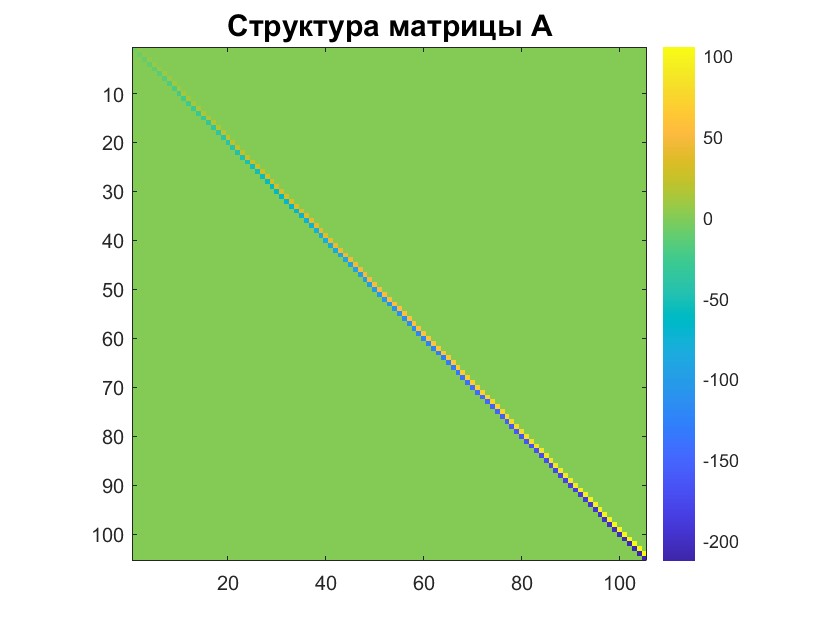

figure(1)
imagesc(A);
title('Структура матрицы A', 'FontSize', TextSize)
axis square;
colorbar;

Нахождение собственных чисел. При нахождении собственных чисел двух матриц A и B функции eig(A, B) можно также передать аргумент 'algorithm', определяющий алгоритм, используемый для их вычисления. Если данный аргумент не указан, а матрица A является симметричной (эрмитовой), матрица B является положительно-определенной, то MATLAB автоматически выберет алгоритм 'chol'. В противном случае, будет использован алгоритм 'qz'.

e = eig(A); % собственные числа матрицы A в виде вектор-столбца

Нахождение L_2-нормы, L_E-нормы, чисел обусловленности матрицы.

L_2 = max(sqrt(eig(transpose(A) * A))); % L_2-норма
cond_2 = L_2 * max(sqrt(eig(transpose(inv(A)) * inv(A)))); % число обусловленности для L_2-нормы

L_E = norm(A, 2); % евклидова норма
cond_E = L_E * norm(inv(A), 2); % число обусловленности для евклидовой нормы

Решение СЛАУ с помощью библиотечных методов MATLAB. Сравнение с методом прогонки. Вывод графиков ошибки и невязки.

tic;
x_mldiv = A \ b_right; % функция mldivide
t1 = toc;

tic;
x_linsol = linsolve(A, b_right); % функция linsolve
t2 = toc;

fprintf('Время исполнения "mldivide": %f.\nВремя исполнения "linsolve": %f.', t1, t2);

Время исполнения "mldivide": 0.004754.
Время исполнения "linsolve": 0.004926.

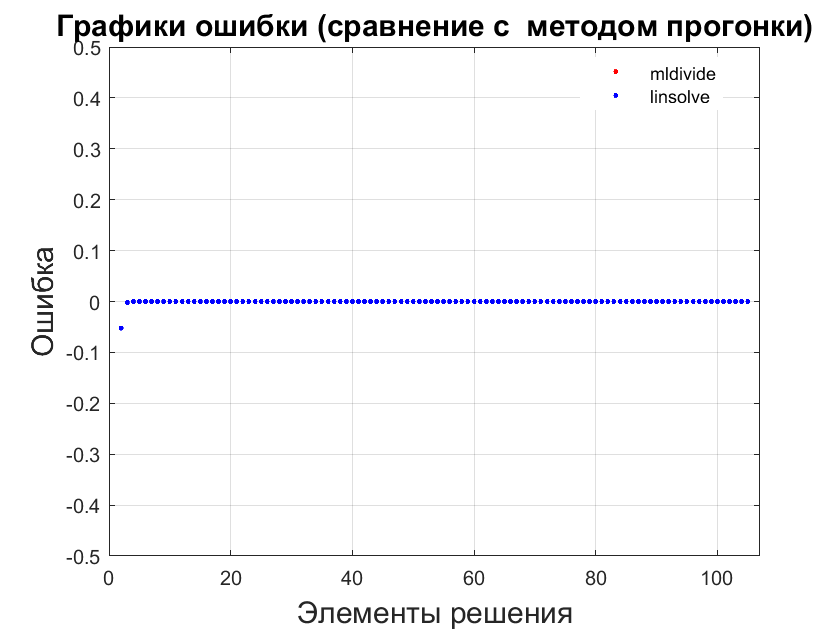

err_tridiag_mldiv = x_mldiv - x;
err_tridiag_linsol = x_linsol - x;

figure(2);
plot(err_tridiag_mldiv, 'r.');
grid on;
title('Графики ошибки (сравнение с  методом прогонки)', 'FontSize', TextSize);
xlabel('Элементы решения', 'FontSize', TextSize);
ylabel('Ошибка', 'FontSize', TextSize);
xlim([0 107]);
ylim([-0.5 0.5]);
hold on;
plot(err_tridiag_linsol, 'b.');
hold off;
legend({'mldivide', 'linsolve'}, 'Location', 'best');

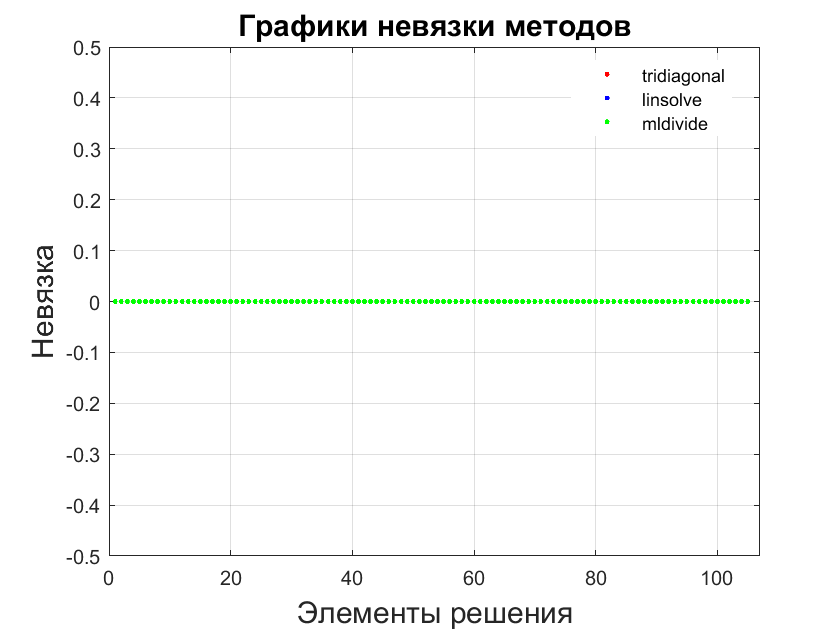

r_mldiv = b_right - A * x_mldiv;
r_linsol = b_right - A * x_linsol;
r_tridiag = b_right - A * x;

figure(3);
plot(r_tridiag, 'r.');
grid on;
title('Графики невязки методов', 'FontSize', TextSize);
xlabel('Элементы решения', 'FontSize', TextSize);
ylabel('Невязка', 'FontSize', TextSize);
xlim([0 107]);
ylim([-0.5 0.5]);
hold on;
plot(r_linsol, 'b.');
plot(r_mldiv, 'g.');
hold off;
legend({'tridiagonal', 'linsolve', 'mldivide'}, 'Location', 'best');

Библиотечные методы решения разреженных СЛАУ. Сравнение с итерационным методом Якоби. Вывод графиков ошибки и невязки.

tic;
x_bicgstab = bicgstab(A, b_right, 1e-6, 70); % стабилизированный метод бисопряжённых градиентов

bicgstab converged at iteration 46.5 to a solution with relative residual 7.4e-07.


t1 = toc;

tic;
x_lsqr = lsqr(A, b_right, 1e-6, 190); % метод наименьших квадратов

lsqr converged at iteration 166 to a solution with relative residual 8.1e-07.


t2 = toc;

fprintf('Время исполнения "bicgstab": %f.\nВремя исполнения "lsqr": %f.', t1, t2);

Время исполнения "bicgstab": 0.016710.
Время исполнения "lsqr": 0.022606.

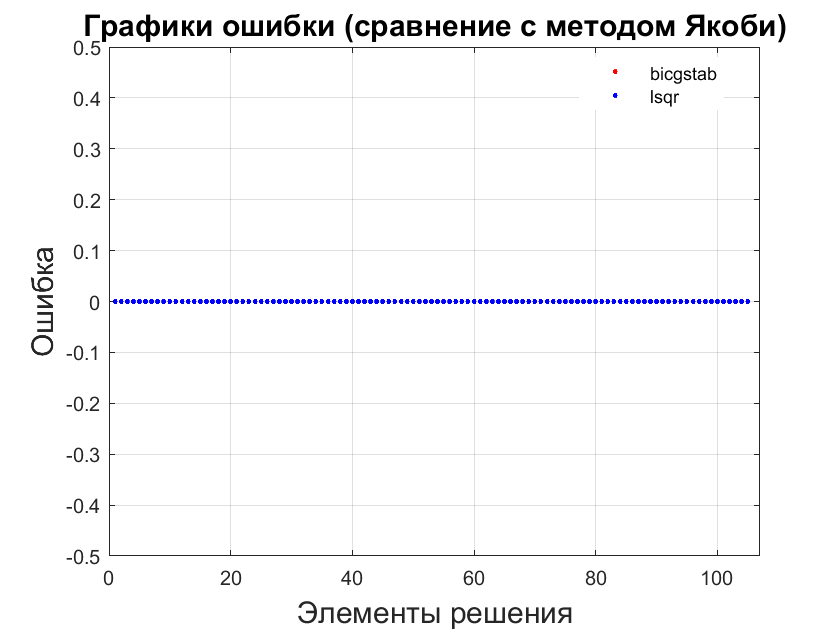

err_jac_bicgstab = x_bicgstab - x_jac_new;
err_jac_lsqr = x_lsqr - x_jac_new;

figure(4);
plot(err_jac_bicgstab, 'r.');
grid on;
title('Графики ошибки (сравнение с методом Якоби)', 'FontSize', TextSize);
xlabel('Элементы решения', 'FontSize', TextSize);
ylabel('Ошибка', 'FontSize', TextSize);
xlim([0 107]);
ylim([-0.5 0.5]);
hold on;
plot(err_jac_lsqr, 'b.');
hold off;
legend({'bicgstab', 'lsqr'}, 'Location', 'best');

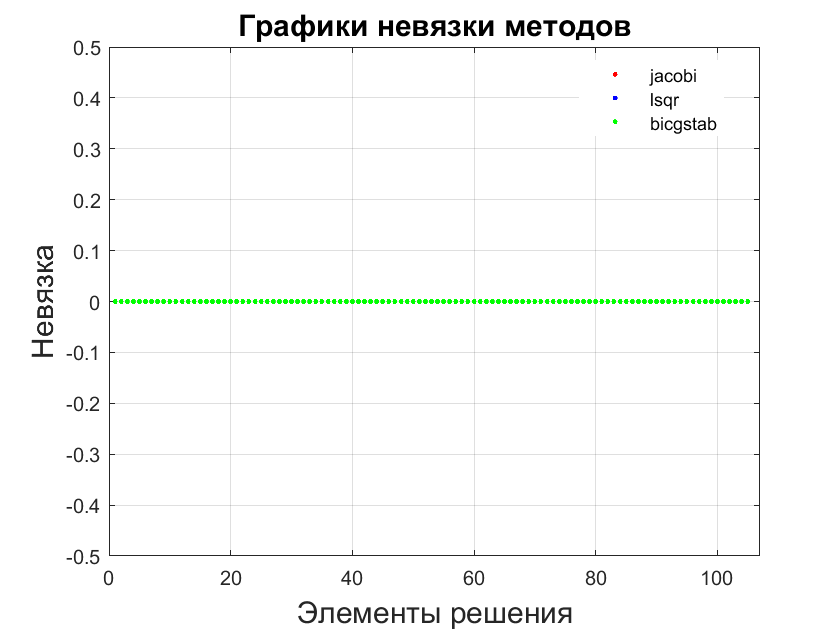

r_bicgstab = b_right - A * x_bicgstab;
r_lsqr = b_right - A * x_lsqr;
r_jac = b_right - A * x_jac_new;

figure(5);
plot(r_jac, 'r.');
grid on;
title('Графики невязки методов', 'FontSize', TextSize);
xlabel('Элементы решения', 'FontSize', TextSize);
ylabel('Невязка', 'FontSize', TextSize);
xlim([0 107]);
ylim([-0.5 0.5]);
hold on;
plot(r_lsqr, 'b.');
plot(r_bicgstab, 'g.');
hold off;
legend({'jacobi', 'lsqr', 'bicgstab'}, 'Location', 'best');